# Estimate Body Pose Using Deep Learning

This example shows how to estimate the body pose of one or more people using the OpenPose algorithm and a pretrained network.

The goal of body pose estimation is to identify the location of people in an image and the orientation of their body parts. When multiple people are present in a scene, pose estimation can be more difficult because of occlusion, body contact, and proximity of similar body parts.

There are two strategies to estimating body pose. A top-down strategy first identifies individual people using object detection and then estimates the pose of each person. A bottom-up strategy first identifies body parts in an image, such as noses and left elbows, and then assembles individuals based on likely pairings of body parts. The bottom-up strategy is more robust to occlusion and body contact, but the strategy is more difficult to implement. OpenPose is a multi-person human pose estimation algorithm that uses a bottom-up strategy [1].

To identify body parts in an image, OpenPose uses a pretrained neural network that predicts heatmaps and part affinity fields (PAFs) for body parts in an input image [2]. Each heatmap shows the probability that a particular type of body part is located at each pixel in the image. The PAFs are vector fields that indicate whether two body parts are connected. For each defined type of body part pairing, such as neck to left shoulder, there are two PAFs that show the x- and y-component of the vector field between instances of the body parts.

To assemble body parts into individual people, the OpenPose algorithm performs a series of post-processing operations. The first operation identifies and localized body parts using the heatmaps returned by the network. Subsequent operations identify actual connections between body parts, resulting in the individual poses. For more details about the algorithm, see Identify Poses from Heatmaps and PAFs.

## Import the Network

Import a pretrained network from an ONNX file.

dataDir = fullfile(tempdir,"OpenPose");
trainedOpenPoseNet_url = "https://ssd.mathworks.com/supportfiles/"+ ...
    "vision/data/human-pose-estimation.zip";
downloadTrainedOpenPoseNet(trainedOpenPoseNet_url,dataDir)
unzip(fullfile(dataDir,"human-pose-estimation.zip"),dataDir);

Download and install the Deep Learning Toolbox™ Converter for ONNX Model Format support package.

If Deep Learning Toolbox Converter™ for ONNX Model Format is not installed, then the function provides a link to the required support package in the Add-On Explorer. To install the support package, click the link, and then click Install. If the support package is installed, then the `importNetworkFromONNX` function returns a `dlnetwork` object.

modelfile = fullfile(dataDir,"human-pose-estimation.onnx");
net = importNetworkFromONNX(modelfile);

Initialize the network using a sample labeled `dlarray` input.

inputSize = net.Layers(1).InputSize;
X = dlarray(rand(inputSize),"SSC");
net = initialize(net,X);

## Predict Heatmaps and PAFs of Test Image

Read and display a test image.

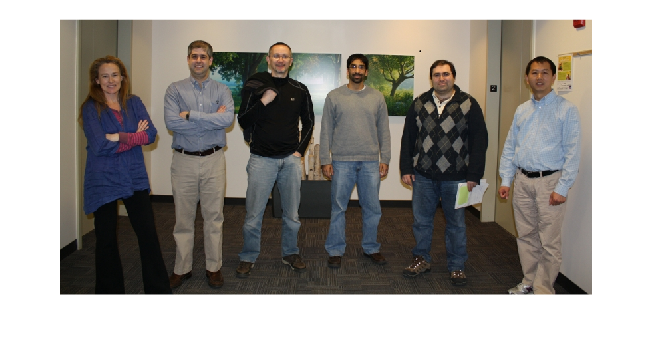

im = imread("visionteam.jpg");
imshow(im)

The network expects image data of data type `single` in the range [-0.5, 0.5]. Shift and rescale the data to this range.

netInput = im2single(im)-0.5;

The network expects the color channels in the order blue, green, red. Switch the order of the image color channels.

netInput = netInput(:,:,[3 2 1]);

Store the image data as a `dlarray`.

netInput = dlarray(netInput,"SSC");

Predict the heatmaps and part affinity fields (PAFs), which are output from the 2-D output convolutional layers.

[heatmaps,pafs] = predict(net,netInput);

Get the numeric heatmap data stored in the `dlarray`. The data has 19 channels. Each channel corresponds to a heatmap for a unique body part, with one additional heatmap for the background. 

heatmaps = extractdata(heatmaps);

Display the heatmaps in a montage, rescaling the data to the range [0, 1] expected of images of data type `single`. The scene has six people, and there are six bright spots in each heatmap.

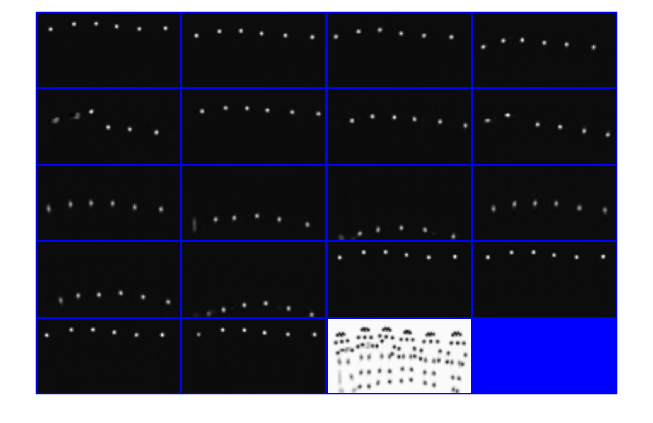

montage(rescale(heatmaps),BackgroundColor="b",BorderSize=3)

To visualize the correspondence of bright spots with the bodies, display the first heatmap in falsecolor over the test image. 

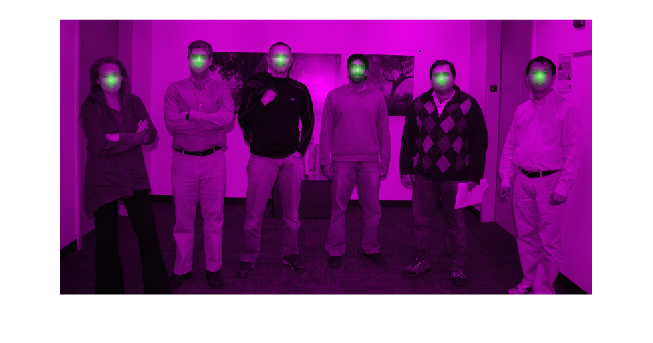

idx = 1;
hmap = heatmaps(:,:,idx);
hmap = imresize(hmap,size(im,[1 2]));
imshowpair(hmap,im);

The OpenPose algorithm does not use the background heatmap to determine the location of body parts. Remove the background heatmap.

heatmaps = heatmaps(:,:,1:end-1);

Get the numeric PAF data stored in the `dlarray`. The data has 38 channels. There are two channels for each type of body part pairing, which represent the x- and y-component of the vector field.

pafs = extractdata(pafs);

Display the PAFs in a montage, rescaling the data to the range [0, 1] expected of images of data type `single`. The two columns show the x- and y-components of the vector field, respectively. The body part pairings are in the order determined by the `params.PAF_INDEX` value.

- Pairs of body parts with a mostly vertical connection have large magnitudes for the y-component pairings and negligible values for the x-component pairings. One example is the  right hip to right knee connection, which appears in the second row. Note that the PAFs depend on the actual poses in the image. An image with a body in a different orientation, such as lying down, will not necessarily have a large y-component magnitude for the right hip to right knee connection.

- Pairs of body parts with a mostly horizontal connection have large magnitudes for the x-component pairings and negligible values for the y-component pairings. One example is the neck to left shoulder connection, which appears in the seventh row.

- Pairs of body part at an angle have values for both x- and y-components of the vector field. One example is the neck to left hip, which appears in the first row.

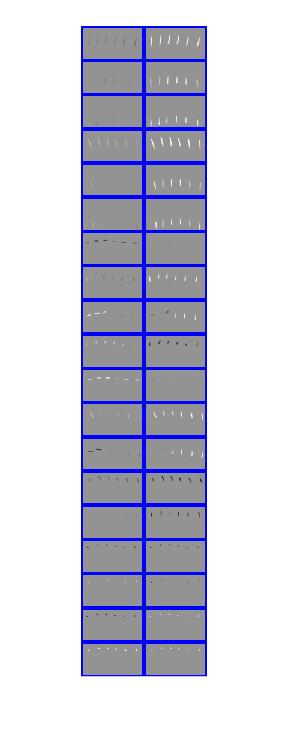

montage(rescale(pafs),Size=[19 2],BackgroundColor="b",BorderSize=3)

To visualize the correspondence of the PAFs with the bodies, display the x- and y-component of the first type of body part pair in falsecolor over the test image.

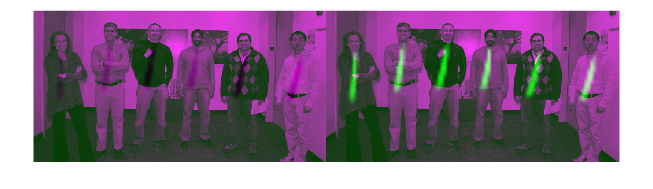

idx = 1;
impair = horzcat(im,im);
pafpair = horzcat(pafs(:,:,2*idx-1),pafs(:,:,2*idx));
pafpair = imresize(pafpair,size(impair,[1 2]));
imshowpair(pafpair,impair);

## Identify Poses from Heatmaps and PAFs

The post-processing part of the algorithm identifies the individual poses of the people in the image using the heatmaps and PAFs returned by the neural network.

Get parameters of the OpenPose algorithm using the `getBodyPoseParameters` helper function. The function is attached to the example as a supporting file. The function returns a struct with parameters such as the number of body parts and connections between body part types to consider. The parameters also include thresholds that you can adjust to improve the performance of the algorithm.

params = getBodyPoseParameters;

Identify individual people and their poses by using the `getBodyPoses` helper function. This function is attached to the example as a supporting file. The helper function performs all post-processing steps for pose estimation:

- Detect the precise body part locations from the heatmaps using nonmaximum suppression.

- For each type of body part pairing, generate all possible pairs between detected body parts. For instance, generate all possible pairs between the six necks and the six left shoulders. The result is a bipartite graph.

- Score the pairs by computing the line integral of the straight line connecting the two detected body parts through the PAF vector field. A large score indicates a strong connection between detected body parts.

- Sort the possible pairs by their scores and find the valid pairs. Valid body part pairs are pairs that connect two body parts that belong to the same person. Typically, pairs with the largest score are considered first because they are most likely to be a valid pair. However, the algorithm compensates for occlusion and proximity using additional constraints. For example, the same person cannot have duplicate pairs of body parts, and one body part cannot belong to two different people.

- Knowing which body parts are connected, assemble the body parts into separate poses for each individual person.

The helper function returns a 3-D matrix. The first dimension represents the number of identified people in the image. The second dimension represents the number of body part types. The third dimension indicates the x- and y-coordinates for each body part of each person. If a body part is not detected in the image, then the coordinates for that part are [NaN NaN].

poses = getBodyPoses(heatmaps,pafs,params);

Display the body poses using the `renderBodyPoses` helper function. This function is attached to the example as a supporting file.

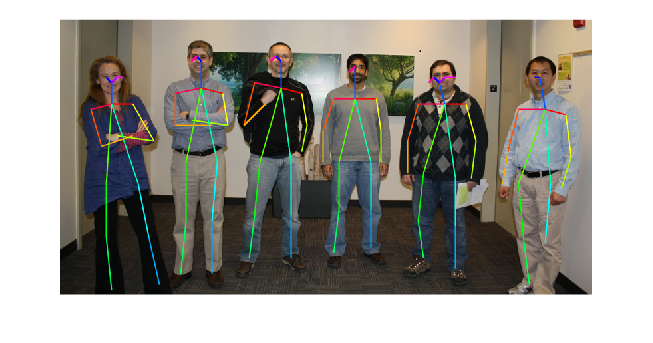

renderBodyPoses(im,poses,size(heatmaps,1),size(heatmaps,2),params);

## References

[1] Cao, Zhe, Gines Hidalgo, Tomas Simon, Shih-En Wei, and Yaser Sheikh. “OpenPose: Realtime Multi-Person 2D Pose Estimation Using Part Affinity Fields.” *ArXiv:1812.08008 [Cs]*, May 30, 2019. [https://arxiv.org/abs/1812.08008](https://arxiv.org/abs/1812.08008).

[2] Osokin, Daniil. “Real-Time 2D Multi-Person Pose Estimation on CPU: Lightweight OpenPose.” *ArXiv:1811.12004 [Cs]*, November 29, 2018. [https://arxiv.org/abs/1811.12004](https://arxiv.org/abs/1811.12004).

*Copyright 2020-2024 The MathWorks, Inc.*